## Definitions of constants/variables

symbol_num = 10000;
symbols = importdata("const_rand_symbols.mat")'; 
%symbols = randi([0 3],1,symbol_num);
const_rand_sym_noise=importdata("const_rand_sym_noise.mat")';
symbol_rate = 100e9; %Hz
time_step = 1/symbol_rate; %seconds
linewidth = 100e3; %Hz
variance=2*pi*linewidth*time_step;

## QPSK

modulated_symbols = pskmod(symbols,4,0,'gray');

demod_symbols = pskdemod(modulated_symbols,4,0,'gray');

%%%Phase noise modeled as random walk%%%
%The cummulative sum of the standard deviations of each symbol's 
% phase as they are passed through the channel

%phase_noise=cumsum(sqrt(variance)randn(symbol_num,1));

sets = logspace(1,9,10);
sets_num = length(sets);

variances = (variance .* sets)';

%phase_noise= cumsum(sqrt(variance)*const_rand_sym_noise);

%phase_noise_sets = zeros(sets_num,symbol_num);

phase_noise_sets = cumsum(sqrt(variances).*const_rand_sym_noise);

noisy_modulated_symbols = modulated_symbols .* exp(1j*phase_noise_sets);

noisy_demod_symbols = pskdemod(noisy_modulated_symbols,4,0,"gray");


## Plotting QPSK output, after noise has been added

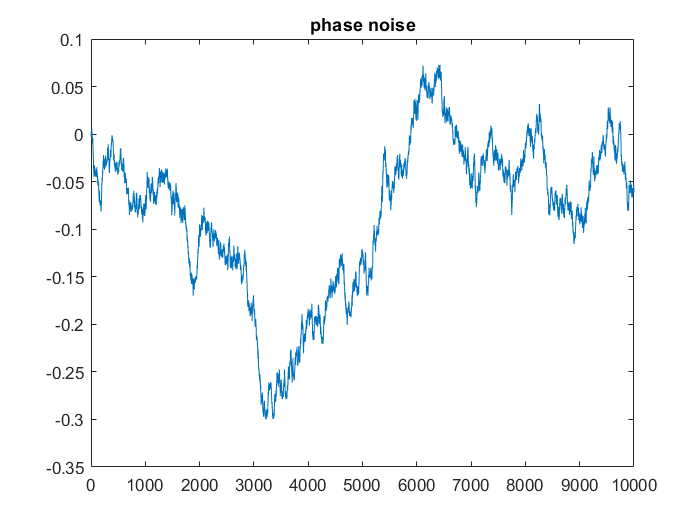

figure
plot(phase_noise)
title('phase noise')

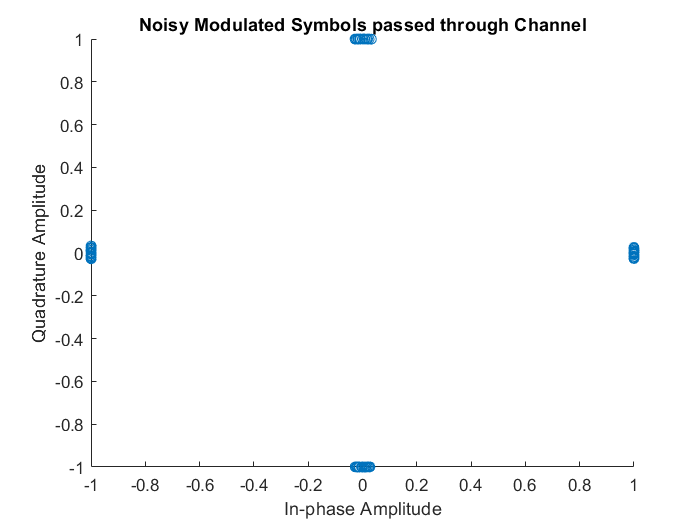


figure
hold on
scatter(real(noisy_modulated_symbols(1,:)),imag(noisy_modulated_symbols(1,:)));
title("Noisy Modulated Symbols passed through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")
hold off

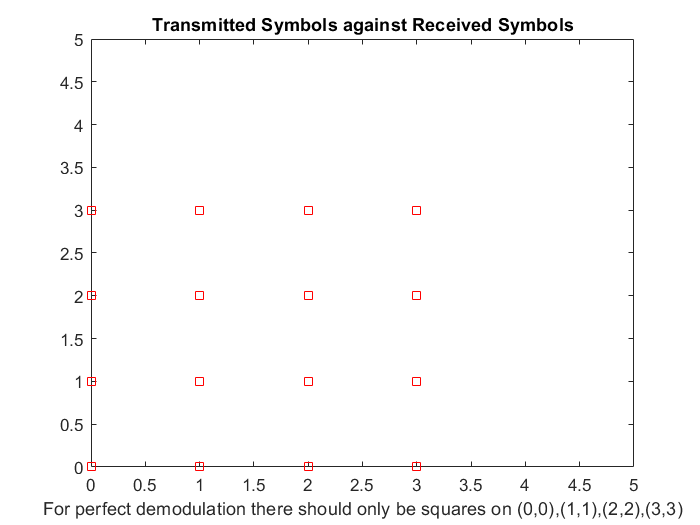

%{
figure
scatter(real(noisy_demod_symbols),imag(noisy_demod_symbols),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")
%}

figure
plot(noisy_demod_symbols,symbols,"rs")
title("Transmitted Symbols against Received Symbols")
xlabel("For perfect demodulation there should only be squares on (0,0),(1,1),(2,2),(3,3)")
%plot(modulated_symbols)
axis([0,5,0,5])

%grid on

## SNR and BER (Random Walk Noise)

[SNR,noisePow,num_of_errs,BER] = deal(zeros(sets_num,1));

figure
hold on
title("SNR vs BER for Random Walk Noise")
for i=size(noisy_demod_symbols,1)
[SNR(i,:),noisePow(i,:)] = snr(symbols(1,:),noisy_demod_symbols(i,:)); %All in dB
[num_of_errs(i,:),BER(i,:)] = biterr(symbols(1,:),noisy_demod_symbols(i,:),2);
end
size(SNR)

ans =     10     1


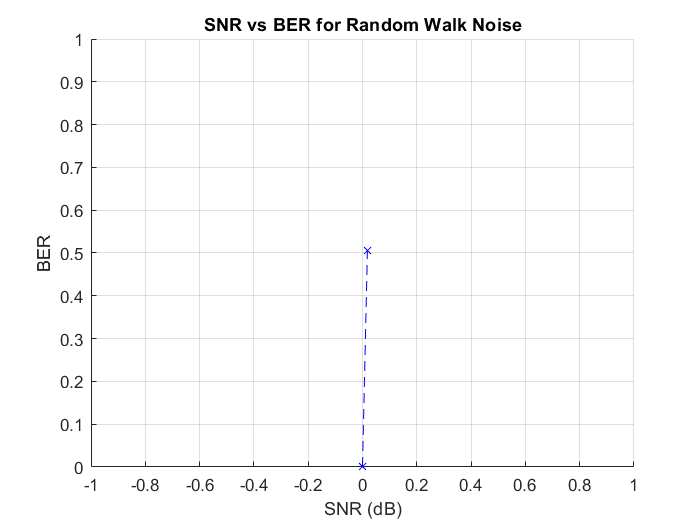

plot(SNR,BER,"bx--")
grid on
xlabel("SNR (dB)")
ylabel("BER")
axis([-1,1,0,1])
hold off

## AWGN Testing

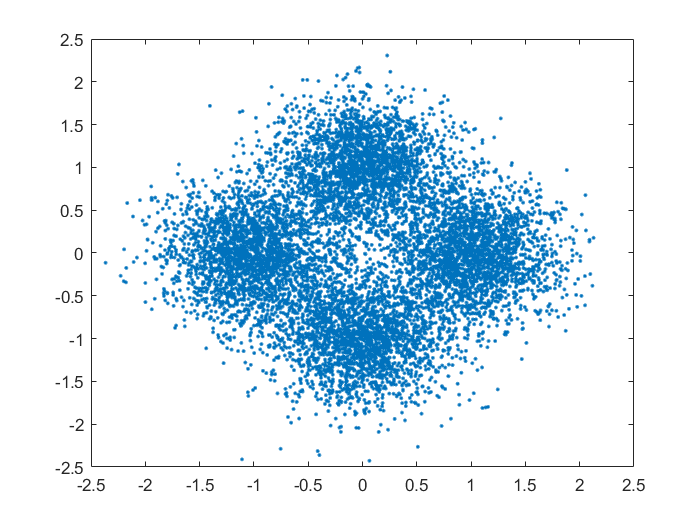

%%Correct Approach
%% SNR uses noise not noisy signals, fix sets
awgn_symbols_1 = awgn(modulated_symbols,5);

plot(awgn_symbols_1,'.')


demoded_symbols = pskdemod(awgn_symbols_1,4,0,"gray")

demoded_symbols =      3     2     0     1     2     0     0     2     1     3     3     3     3     0     0     2     1     3     3     2     2     3     3     3     3     2     3     2     1     0     0     3     0     1     0     3     3     1     1     1     0     2     1     0     1     3     1     0     1     0


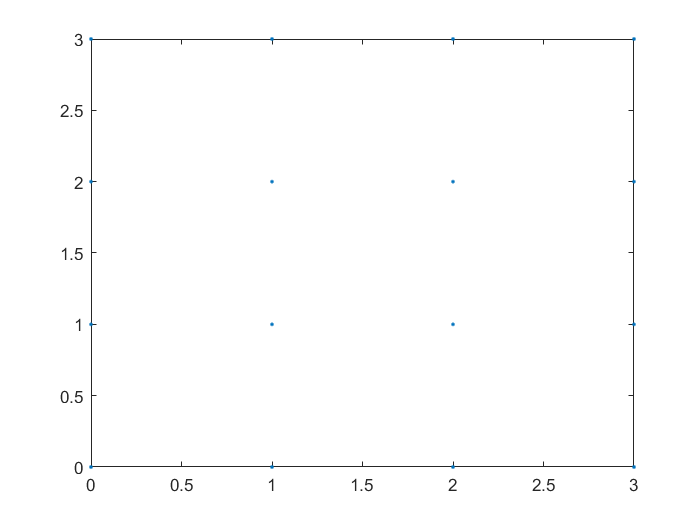


plot(demoded_symbols,symbols,'.')

measured_SNR = snr(abs(modulated_symbols),abs(awgn_symbols_1 - modulated_symbols))

measured_SNR = 5.0429

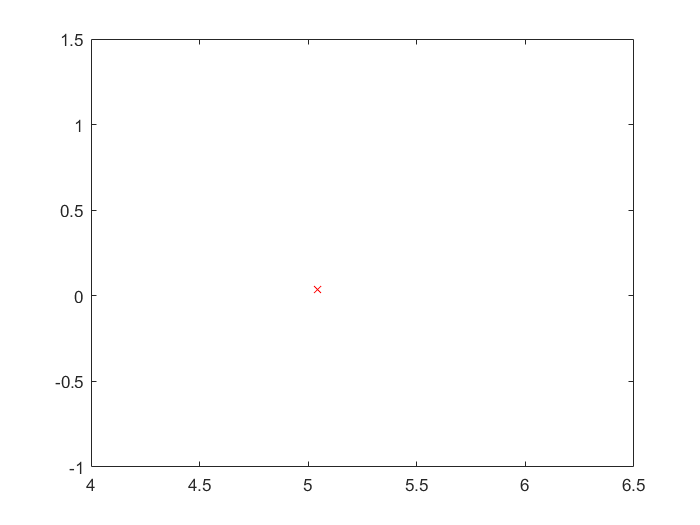


[errs,BER] = biterr(symbols,demoded_symbols,2);

plot(measured_SNR,BER,"-rx")

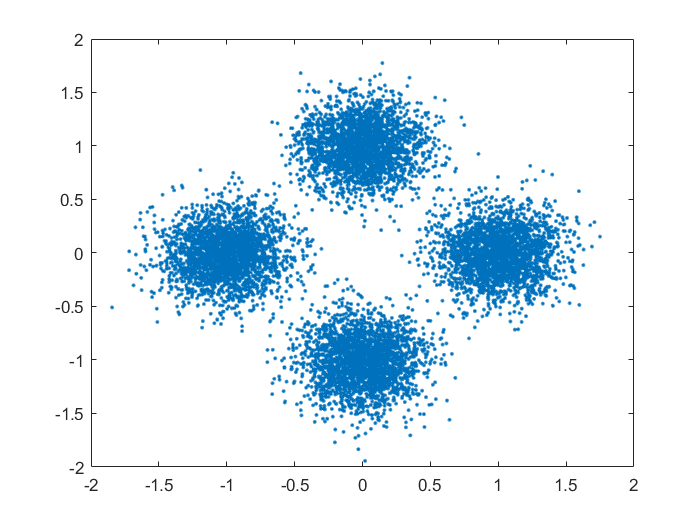

snr_val = linspace(1,20,20);

awgn_symbols = zeros(size(snr_val,2),symbol_num);

for i=1:size(snr_val,2)
    awgn_symbols(i,:) = awgn(modulated_symbols,snr_val(1,i));
end
plot(awgn_symbols(10,:),'.')

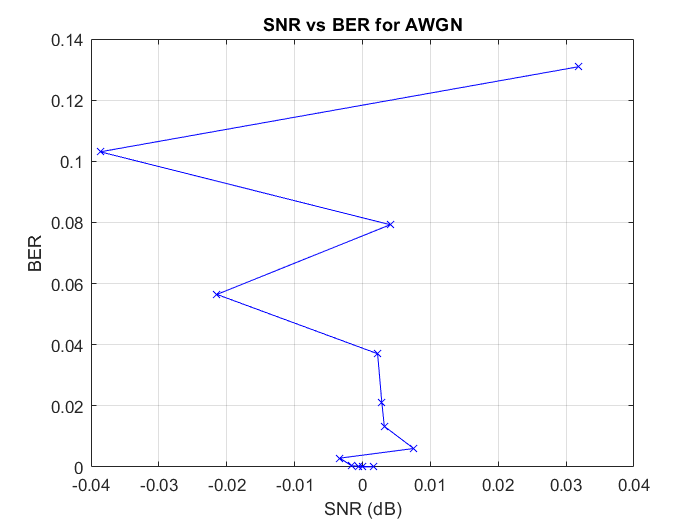

awgn_demod_symbols = pskdemod(awgn_symbols,4,0,"gray");

for i=1:size(awgn_demod_symbols)
    [SNR(i),noisePow(i)] = snr(symbols,awgn_demod_symbols(i,:)); %All in dB
    [num_of_errs(i),BER(i)] = biterr(symbols,awgn_demod_symbols(i,:),2);
end
figure
plot(SNR,BER,"-bx")
title("SNR vs BER for AWGN")
grid on
xlabel("SNR (dB)")
ylabel("BER")

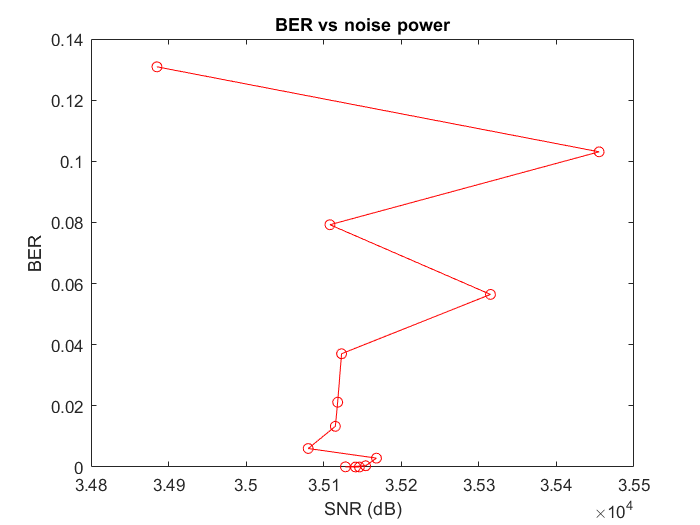

%axis([-1,1,0,1])


plot(noisePow,BER,'-ro')
title("BER vs noise power")
xlabel("SNR (dB)")
ylabel("BER")

## Filtering/Oversampling

%{
symbol_rate = 100e9; 
time_step = 1/symbol_rate; 
linewidth = 100e3;
variance=2*pi*linewidth*time_step;}
%}

sampling=time_step/4;

oversampling = 4;
rrc_filter= rcosdesign(0.2,10,oversampling);
sampled_symbols = upfirdn(noisy_modulated_symbols',rrc_filter,oversampling);

%eyediagram(sampled_symbols(2:10000,1),oversampling);
%kron product

%scope = dsp.SpectrumAnalyzer(2);

%TO DO
% Modulate transceiver with raised cosine and match on receiver
%kroneker tensor product (for oversampling)
a=kron([1,2,3],[1,0,0,0])

a =      1     0     0     0     2     0     0     0     3     0     0     0


## Spectral Analysis

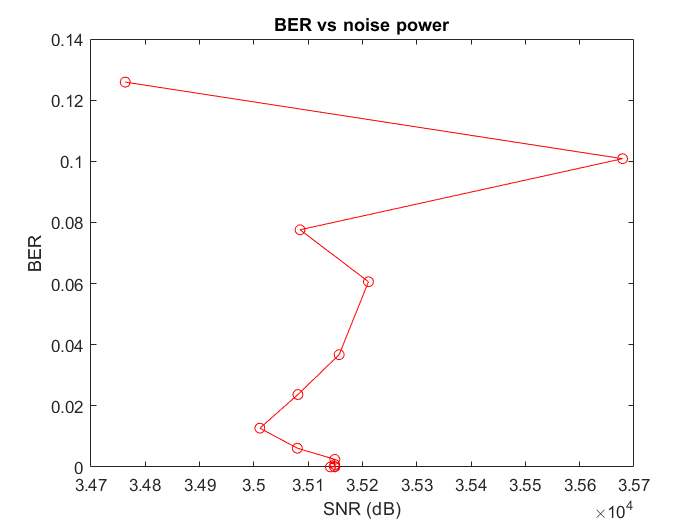

%noisy_modulated_symbols
%symbol_num
%symbol_rate
%time_step

%%Change the symbols to be a known frequency
hold off

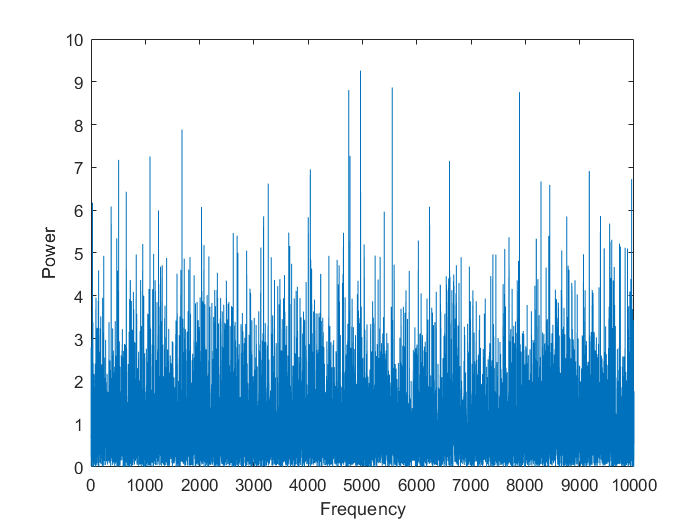

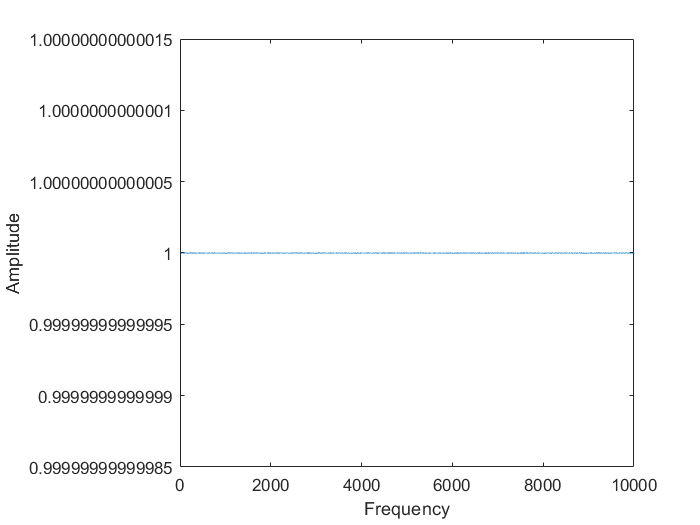

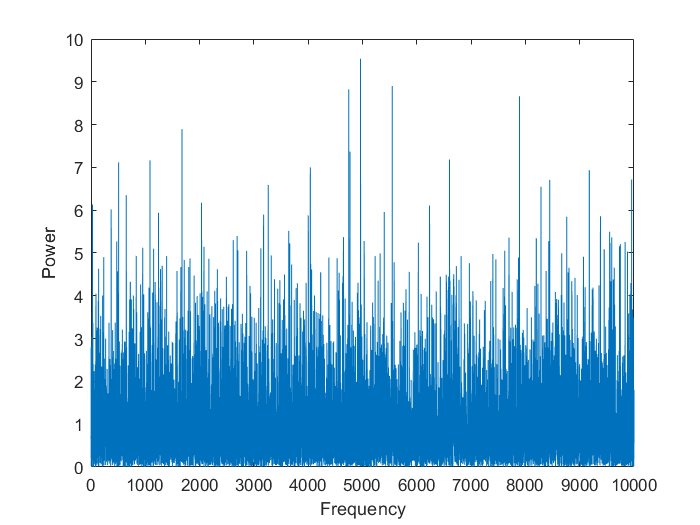

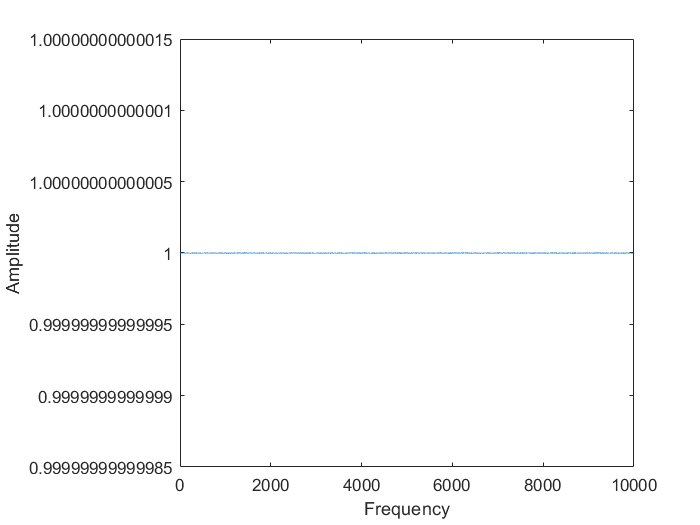

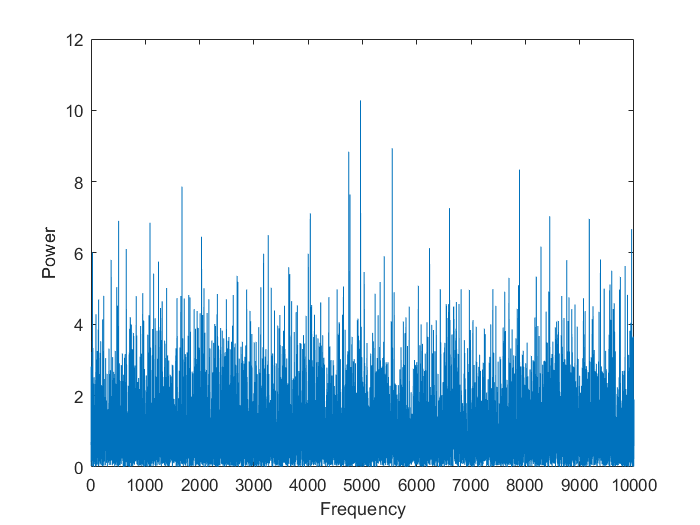

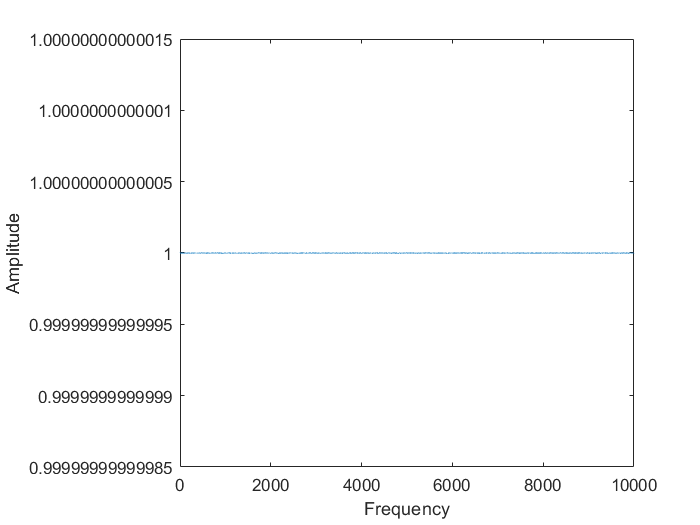

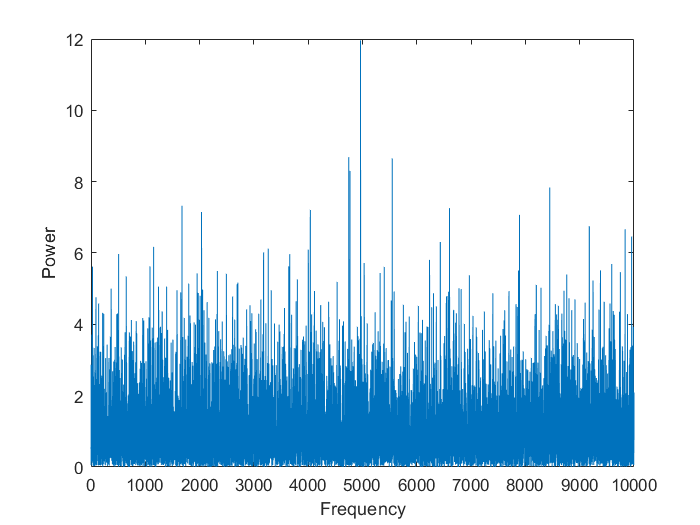

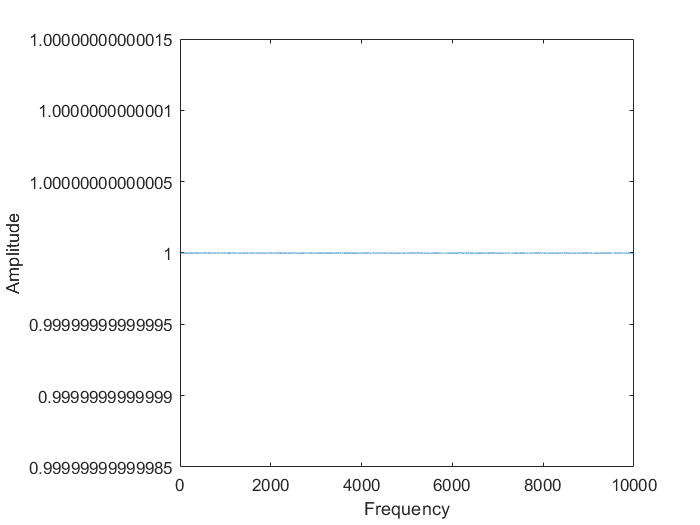

t = (0:symbol_num-1)/symbol_rate;
freq_inc = symbol_rate/symbol_num;
nyq_freq = symbol_rate/2;
y = zeros(sets_num,symbol_num);
amplitude = zeros(sets_num,symbol_num);
power = zeros(sets_num,symbol_num);

for i=1:size(noisy_modulated_symbols)
    y(i,:) = fft(noisy_modulated_symbols(i,:));
    amplitude(i,:) = abs(noisy_modulated_symbols(i,:));
    power(i,:) = (abs(y(i,:)).^2)/symbol_num;
end

for i=1:10
figure
plot(power(i,:));
xlabel("Frequency");
ylabel("Power");

figure
plot(amplitude(i,:));
xlabel("Frequency");
ylabel("Amplitude");
end


%Friday 13th presentation